# **Example of figures for chemostat/retentostat fits with variants 1 and 2**

## Calling parameter values 

The different variants has to be activated depending on the results. Ex. For a chemostat fit on variant 1, activate the file Variant 1 - Chemsotat. 

% Variant 1 - Chemostat %
load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\variant_1_chemostat.mat')
% Variant 1 - Retentostat %
% load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\variant_1_retentostat.mat')
% Variant 2 - Chemostat %
% load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\variant_2_chemostat.mat')
% Variant 2 - Retentostat %
% load('C:\Doctorado\Programa\Nuevo_PECCAD\NEW ATRAZINE\GENE BASED MODELS\AT_engi_soil\example_parameter_fits\variant_2_retentostat.mat')


## Defining parameters as input of the model 

p1 = p;

## Calling fixed parameters 

delta13_I = (-29/1000);
AT_tot    =  30000*(8*12/216);                  % Input of AT, including light and heavy isotopologues [micro g C/L].
frac_coef = -0.0054;                            % Initial fraction Coefficient "epsilon" for the AT applied in the experiment.
SN        = (delta13_I+1)*0.011180;             % Initial C13/C12. -29 is taken from Ehrl. et al 2019 paper (-29 per mil).

q(2) = AT_tot;                                  % Concentration of light AT in the inlet [microg C/L].
q(3) = AT_tot*SN;                               % Concentration of heavier AT in the inlet [microg C/L].
q(4) = 1;                                       % Factor for chemostat (1) and retentostat (0).
q(5) = 8*12/216;                                % mg C/mg AT.
q(6) = 8*12/197;                                % mg C/mg HY.
q(7) = 1e-15;                                   % Volume of a single bacterium [L].
q(8) = 1+frac_coef;                             % Isotopic fractionation factor "alpha" that comes from the enzymatic activity [-].
q(9) = 0.011180;                                % reference isotope ratio of VPDB (Vienna Pee Dee Belemnite) [-].

## Calling the model

% ODE Options %

abstol = 1e-9;
reltol = 1e-7;
o_opts = odeset('AbsTol',abstol,'RelTol',reltol,'Events',@stopevent,'NonNegative',1:7);

% Extra Parameters %

T_bioC   = 3.66e11;  % Initial Biomass [cells/L]
fcell    = 10^p1(7);
C_AT     = q(5);     % µg C/µg AT
C_HY     = q(6);     % µg C/µg HY
ATinitC  = 87*C_AT;  % µg C/ L OUTSIDE
HYinitC  = 18*0;     % µg C/ L OUTSIDE
isf      = q(8);     % Isotopic fractionation factor (?)
Ref      = q(9);     % reference isotope ratio of VPDB
T_bioR   = 5.4e10;   % Initial Biomass [cells/L]
ATinitR  = 100*C_AT; % microgr/ L OUTSIDE
HYinitR  = 250*C_HY; % microgr/ L OUTSIDE 

% Initial Conditions %

        c(1)    = T_bioC*fcell;                  % Active bacteria A biomass [µg C/L]
        c(2)    = ATinitC;                       % Lighter AT inside the cell in the system in solution [µg C/L]
        c(3)    = ATinitC*SN;                    % Heavier AT inside the cell in the system in solution [µg C/L]
        c(4)    = ATinitC;                       % Lighter AT outside the cell in the system in solution [µg C/L]
        c(5)    = ATinitC*SN;                    % Heavier AT outside the cell in the system in solution [µg C/L]
        c(6)    = HYinitC;                       % Hydroxyatrazine INSIDE the cell [µg C/L]
        c(7)    = HYinitC;                       % Hydroxyatrazine outisde the cell [µg C/L]


## Running ODE for Chemostat 

Here, we give the example of the model variant 1, but this can be chaged to model variant 2. 

% First Dilution Rate %

q(1)    = 0.023*24;    % Dilution rate coeficient (1/d)
t       = [0 20];
tic
[ty,cu] = ode15s(@variant_1,t,c,o_opts,p1',q);

% Second Dilution Rate %

q(1) = 0.032*24;       % Dilution rate coeficient (1/d)        
t1   = [20 31];

        c(1)    = cu(end,1);                % Active bacteria A biomass [µg C/L]
        c(2)    = cu(end,2);                % Lighter AT inside the cell in the system in solution [µg C/L]
        c(3)    = cu(end,3);                % Heavier AT inside the cell in the system in solution [µg C/L]
        c(4)    = cu(end,4);                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(5)    = cu(end,5);                % Heavier AT outside the cell in the system in solution [µg C/L]
        c(6)    = cu(end,6);                % Hydroxyatrazine INSIDE the cell [µg C/L]
        c(7)    = cu(end,7);                % Hydroxyatrazine outisde the cell [µg C/L]

tic
[ty1,cu1] = ode15s(@variant_1,t1,c,o_opts,p1',q);

% Third dilution rate %

q(1) = 0.048*24;       % Dilution rate coeficient (1/d)        
t2   = [31 37];

        c(1)    = cu1(end,1);                % Active bacteria A biomass [µg C/L]
        c(2)    = cu1(end,2);                % Lighter AT inside the cell in the system in solution [µg C/L]
        c(3)    = cu1(end,3);                % Heavier AT inside the cell in the system in solution [µg C/L]
        c(4)    = cu1(end,4);                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(5)    = cu1(end,5);                % Heavier AT outside the cell in the system in solution [µg C/L]
        c(6)    = cu1(end,6);                % Hydroxyatrazine INSIDE the cell [µg C/L]
        c(7)    = cu1(end,7);                % Hydroxyatrazine outisde the cell [µg C/L]

tic
[ty2,cu2] = ode15s(@variant_1,t2,c,o_opts,p1',q);

% Fourth dilution rate %

q(1) = 0.056*24;       % Dilution rate coeficient (1/d)        
t3   = [37 42];

        c(1)    = cu2(end,1);                % Active bacteria A biomass [µg C/L]
        c(2)    = cu2(end,2);                % Lighter AT inside the cell in the system in solution [µg C/L]
        c(3)    = cu2(end,3);                % Heavier AT inside the cell in the system in solution [µg C/L]
        c(4)    = cu2(end,4);                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(5)    = cu2(end,5);                % Heavier AT outside the cell in the system in solution [µg C/L]
        c(6)    = cu2(end,6);                % Hydroxyatrazine INSIDE the cell [µg C/L]
        c(7)    = cu2(end,7);                % Hydroxyatrazine outisde the cell [µg C/L]
            
tic
[ty3,cu3] = ode15s(@variant_1,t3,c,o_opts,p1',q);  

% Fifth dilution rate %

q(1) = 0.068*24;       % Dilution rate coeficient (1/d)        
t4   = [42 45];

        c(1)    = cu3(end,1);                % Active bacteria A biomass [µg C/L]
        c(2)    = cu3(end,2);                % Heavier AT inside the cell in the system in solution [µg C/L]
        c(3)    = cu3(end,3);                % Lighter AT inside the cell in the system in solution [µg C/L]
        c(4)    = cu3(end,4);                % Heavier AT outside the cell in the system in solution [µg C/L]
        c(5)    = cu3(end,5);                % Lighter AT outside the cell in the system in solution [µg C/L]
        c(6)    = cu3(end,6);                % Hydroxyatrazine INSIDE the cell [µg C/L]
        c(7)    = cu3(end,7);                % Hydroxyatrazine outisde the cell [µg C/L]     

tic
[ty4,cu4] = ode15s(@variant_1,t4,c,o_opts,p1',q);


## Running ODE for Retentostat

q(1) = 0.02*24;       % Dilution rate coeficient (1/d)        
t5   = [0 100];
q(4) = 0;                                    % Factor for chemostat (1) and retentostat (0).

        c(1)    = T_bioR*fcell;              % Active bacteria A biomass [µg C/L]
        c(2)    = cu4(end,2);                % Lighter AT inside the cell in the system in solution [µg C/L]
        c(3)    = cu4(end,3);                % Heavier AT inside the cell in the system in solution [µg C/L]
        c(4)    = ATinitR;                   % Lighter AT outside the cell in the system in solution [µg C/L]
        c(5)    = ATinitR*SN;                % Heavier AT outside the cell in the system in solution [µg C/L]
        c(6)    = cu4(end,6);                % Hydroxyatrazine INSIDE the cell [µg C/L]
        c(7)    = HYinitR;                   % Hydroxyatrazine outisde the cell [µg C/L]

tic
[ty5,cu5] = ode15s(@variant_1,t5,c,o_opts,p1',q);

## Adequation for plotting - Chemostat

        Lcellc       = vertcat(cu(:,1),cu1(:,1),cu2(:,1),cu3(:,1),cu4(:,1))/fcell;      % Biomass 
        AT_outlc     = vertcat(cu(:,4),cu1(:,4),cu2(:,4),cu3(:,4),cu4(:,4))/C_AT;       % AT lighter
        AT_outhc     = vertcat(cu(:,5),cu1(:,5),cu2(:,5),cu3(:,5),cu4(:,5))/C_AT;       % AT heavier 
        AT_outTc     = AT_outlc + AT_outhc;                                             % Total AT
        HY_outc      = vertcat(cu(:,7),cu1(:,7),cu2(:,7),cu3(:,7),cu4(:,7))/C_HY;       % HY
        k_m_h        = 10^p1(3);
        K_m_h        = 10^p1(4);
        C_HYc        = HY_outc; 
        r_HYc        = k_m_h.*(vertcat(cu(:,7),cu1(:,7),cu2(:,7),cu3(:,7),cu4(:,7))).*...
                      (K_m_h+(vertcat(cu(:,7),cu1(:,7),cu2(:,7),cu3(:,7),cu4(:,7)))).^(-1);
        Timeoc       = vertcat(ty,ty1,ty2,ty3,ty4);                                 % Time

        d_not_i      = -29/1000;                    % Epsilon notation for the inlet.
        d_not_o      = (cu(:,5)./cu(:,4)/Ref)-1;    % Epsilon for the outlet in the chemostat.
        EF_Ch        = (d_not_i - d_not_o);    

## Adequation for plotting - Retentostat

        Lcellr       = (cu5(:,1))/fcell;    % Biomass 
        AT_outlr     = (cu5(:,4))/C_AT;     % AT lighter
        AT_outhr     = (cu5(:,5))/C_AT;     % AT heavier 
        AT_outTr     = AT_outlr + AT_outhr; % Total AT
        HY_outr      = (cu5(:,7))/C_HY;     % HY
        k_m_h        = 10^p1(3);
        K_m_h        = 10^p1(4);
        C_HY         = HY_outr; 
        r_HY         = k_m_h.*cu5(:,7).*(K_m_h+cu5(:,7)).^(-1);
        Timeor       = (ty5);               % Time
        
        d_not_oR     = (cu5(:,5)./cu5(:,4)/Ref)-1;  % ?-notation for the outlet in the chemostat.
        EF_Rt        = (d_not_i - d_not_oR);

## Test for plotting for Chemostat

These plots are only for illustration and were used as preliminary exploration of the validity of our model formulations.

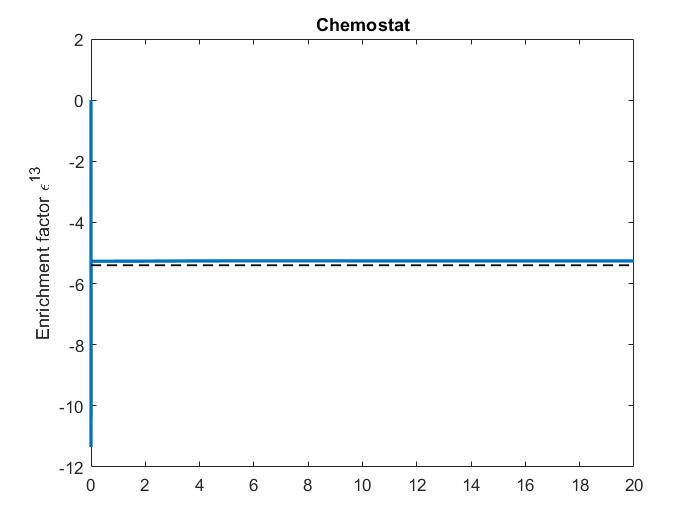

figure ('Name','Enrichment Factor Chemostat')
plot(ty,EF_Ch*1e3,'LineWidth',2)
hold on
plot([0 20],[-5.4 -5.4],'--','Color','black','LineWidth',1)
title('Chemostat')
ylabel('Enrichment factor \epsilon^{13}')
box on
hold off

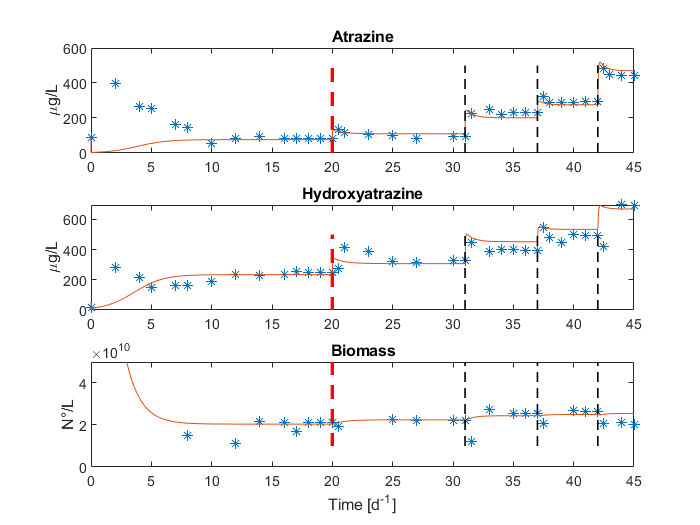


% Calling Data %

load('chemostat_data_plot_test.txt')
Time1 = chemostat_data_plot_test(:,1);
Data1 = chemostat_data_plot_test(:,3);

figure ('Name','AT-Chemostat')
subplot (3,1,1);
plot(Time1(1:37),Data1(1:37),'*')
hold on
plot(Timeoc,AT_outTc)
plot([20 20],[0 500],'--','Color','red','LineWidth',2)
plot([31 31],[0 500],'--','Color','black','LineWidth',1)
plot([37 37],[0 500],'--','Color','black','LineWidth',1)
plot([42 42],[0 500],'--','Color','black','LineWidth',1)
ylabel('\mug/L')
title('Atrazine')
hold off

subplot (3,1,2);
plot(Time1(49:84),Data1(49:84),'*')
hold on
plot(Timeoc,HY_outc)
plot([20 20],[0 500],'--','Color','red','LineWidth',2)
plot([31 31],[0 500],'--','Color','black','LineWidth',1)
plot([37 37],[0 500],'--','Color','black','LineWidth',1)
plot([42 42],[0 500],'--','Color','black','LineWidth',1)
ylabel('\mug/L')
title('Hydroxyatrazine')
hold off

subplot (3,1,3);
plot(Time1(96:122),Data1(96:122),'*')
hold on
plot(Timeoc,Lcellc)
plot([20 20],[1e10 1e13],'--','Color','red','LineWidth',2)
plot([31 31],[1e10 1e13],'--','Color','black','LineWidth',1)
plot([37 37],[1e10 1e13],'--','Color','black','LineWidth',1)
plot([42 42],[1e10 1e13],'--','Color','black','LineWidth',1)
xlabel('Time [d^{-1}]')
ylabel('N°/L')
title('Biomass')
ylim([0,5e10])
hold off  

## Test for plotting for Retentostat

figure ('Name','Enrichment Factor Retentostat')   
plot(ty5,EF_Rt*1e3,'LineWidth',2)
hold on
plot([0 40],[-0.45 -0.45],'--','Color','black','LineWidth',1)
xlabel('Time [d^{-1}]')
title('Retentostat')
box on
ylabel('Enrichment factor \epsilon^{13}')
hold off

% Calling Data %

load('retentostat_data_plot_test.txt')
Time1 = retentostat_data_plot_test(:,1);
Data1 = retentostat_data_plot_test(:,3);

figure ('Name','AT-Retentostat')
subplot (3,1,1);
plot(Time(1:17),Data(1:17),'*')
hold on
plot(Timeor,AT_outTr)
ylabel('\mug/L')
title('Atrazine')
hold off

subplot (3,1,2);
plot(Time(18:34),Data(18:34),'*')
hold on
plot(Timeor,HY_outr)
ylabel('\mug/L')
title('Hydroxyatrazine')
hold off

subplot (3,1,3);
plot(Time(35:end),Data(35:end),'*')
hold on
plot(Timeor,Lcellr)
xlabel('Time [d^{-1}]')
ylabel('N°/L')
title('Biomass')
hold off  